% Step 1: Feature Extraction
disp('Starting Feature Extraction...');

Starting Feature Extraction...



% Define paths for datasets
train_folder = 'Train';
train_features_folder = 'features/Train_MFCC';
test_folder = 'Test';
test_features_folder = 'features/Test_MFCC';
custom_folder = 'Custom';
custom_features_folder = 'features/Custom_MFCC';

% Create output directories if they don't exist
if ~isfolder(train_features_folder)
    mkdir(train_features_folder);
end
if ~isfolder(test_features_folder)
    mkdir(test_features_folder);
end
if ~isfolder(custom_features_folder)
    mkdir(custom_features_folder);
end

% % Extract features for training, testing, and custom datasets
disp('Extracting Training Features...');

Extracting Training Features...


feature_extraction(train_folder, train_features_folder);

Feature file: features/Train_MFCC/sp01a_w04_had.mat
MFCCs size: [13 49]
MFCC dimensions for /Users/myonyinyimin/Documents/MATLAB/Audio-2/Train/had/sp01a_w04_had.mp3: [13 49]
MFCC features saved to features/Train_MFCC/sp01a_w04_had.mat
Feature file: features/Train_MFCC/sp02a_w04_had.mat
MFCCs size: [13 40]
MFCC dimensions for /Users/myonyinyimin/Documents/MATLAB/Audio-2/Train/had/sp02a_w04_had.mp3: [13 40]
MFCC features saved to features/Train_MFCC/sp02a_w04_had.mat
Feature file: features/Train_MFCC/sp04a_w04_had.mat
MFCCs size: [13 33]
MFCC dimensions for /Users/myonyinyimin/Documents/MATLAB/Audio-2/Train/had/sp04a_w04_had.mp3: [13 33]
MFCC features saved to features/Train_MFCC/sp04a_w04_had.mat
Feature file: features/Train_MFCC/sp05a_w04_had.mat
MFCCs size: [13 42]
MFCC dimensions for /Users/myonyinyimin/Documents/MATLAB/Audio-2/Train/had/sp05a_w04_had.mp3: [13 42]
MFCC features saved to features/Train_MFCC/sp05a_w04_had.mat
Feature file: features/Train_MFCC/sp07a_w04_had.mat
MFCCs si


disp('Extracting Testing Features...');

Extracting Testing Features...


feature_extraction(test_folder, test_features_folder);

Feature file: features/Test_MFCC/sp03a_w04_had.mat
MFCCs size: [13 32]
MFCC dimensions for /Users/myonyinyimin/Documents/MATLAB/Audio-2/Test/had/sp03a_w04_had.mp3: [13 32]
MFCC features saved to features/Test_MFCC/sp03a_w04_had.mat
Feature file: features/Test_MFCC/sp10a_w04_had.mat
MFCCs size: [13 33]
MFCC dimensions for /Users/myonyinyimin/Documents/MATLAB/Audio-2/Test/had/sp10a_w04_had.mp3: [13 33]
MFCC features saved to features/Test_MFCC/sp10a_w04_had.mat
Feature file: features/Test_MFCC/sp12a_w04_had.mat
MFCCs size: [13 38]
MFCC dimensions for /Users/myonyinyimin/Documents/MATLAB/Audio-2/Test/had/sp12a_w04_had.mp3: [13 38]
MFCC features saved to features/Test_MFCC/sp12a_w04_had.mat
Feature file: features/Test_MFCC/sp15a_w04_had.mat
MFCCs size: [13 44]
MFCC dimensions for /Users/myonyinyimin/Documents/MATLAB/Audio-2/Test/had/sp15a_w04_had.mp3: [13 44]
MFCC features saved to features/Test_MFCC/sp15a_w04_had.mat
Feature file: features/Test_MFCC/sp19a_w04_had.mat
MFCCs size: [13 40]
M


disp('Extracting Custom Features...');

Extracting Custom Features...


feature_extraction(custom_folder, custom_features_folder);

Feature file: features/Custom_MFCC/sp06a_w04_had.mat
MFCCs size: [13 50]
MFCC dimensions for /Users/myonyinyimin/Documents/MATLAB/Audio-2/Custom/had/sp06a_w04_had.mp3: [13 50]
MFCC features saved to features/Custom_MFCC/sp06a_w04_had.mat
Feature file: features/Custom_MFCC/sp08a_w04_had.mat
MFCCs size: [13 40]
MFCC dimensions for /Users/myonyinyimin/Documents/MATLAB/Audio-2/Custom/had/sp08a_w04_had.mp3: [13 40]
MFCC features saved to features/Custom_MFCC/sp08a_w04_had.mat
Feature file: features/Custom_MFCC/sp18a_w04_had.mat
MFCCs size: [13 38]
MFCC dimensions for /Users/myonyinyimin/Documents/MATLAB/Audio-2/Custom/had/sp18a_w04_had.mp3: [13 38]
MFCC features saved to features/Custom_MFCC/sp18a_w04_had.mat
Feature file: features/Custom_MFCC/sp01a_w05_hard.mat
MFCCs size: [13 68]
MFCC dimensions for /Users/myonyinyimin/Documents/MATLAB/Audio-2/Custom/hard/sp01a_w05_hard.mp3: [13 68]
MFCC features saved to features/Custom_MFCC/sp01a_w05_hard.mat
Feature file: features/Custom_MFCC/sp19a_w05


disp('Feature Extraction Complete.');

Feature Extraction Complete.




% Initialize HMM for the word
disp('Initializing HMMs...');

Initializing HMMs...



% Define vocabulary
words = {'heed', 'hid', 'head', 'had', 'hard', 'hud', 'hod', 'hoard', 'hood', 'whod', 'heard'};

initialize_hmm;

Initializing HMM for the word: heed
Pattern: features/Train_MFCC/*_w*_heed.mat
Aggregating features for word: heed
Number of files for heed: 21
Loading file: sp01a_w01_heed.mat
Loading file: sp02a_w01_heed.mat
Loading file: sp04a_w01_heed.mat
Loading file: sp06a_w01_heed.mat
Loading file: sp07a_w01_heed.mat
Loading file: sp11a_w01_heed.mat
Loading file: sp12a_w01_heed.mat
Loading file: sp13a_w01_heed.mat
Loading file: sp14a_w01_heed.mat
Loading file: sp15a_w01_heed.mat
Loading file: sp17a_w01_heed.mat
Loading file: sp18a_w01_heed.mat
Loading file: sp19a_w01_heed.mat
Loading file: sp21a_w01_heed.mat
Loading file: sp22a_w01_heed.mat
Loading file: sp23a_w01_heed.mat
Loading file: sp24a_w01_heed.mat
Loading file: sp25a_w01_heed.mat
Loading file: sp28a_w01_heed.mat
Loading file: sp29a_w01_heed.mat
Loading file: sp30a_w01_heed.mat
HMM initialized and saved for the word: heed
Initializing HMM for the word: hid
Pattern: features/Train_MFCC/*_w*_hid.mat
Aggregating features for word: hid
Number

% end

disp('Starting HMM Training...');

Starting HMM Training...


Train_hmm();

Training HMM for the word: heed
Aggregated Features for heed: [13 822]
Feature Values Range: [-11.4531, 11.8331]
Iteration: 1
Updated Mean: [1.83838270181877 2.7939954487561 3.88497297052195 4.6732898457471 5.09121155541201 5.20160859447688 5.11885080644909 4.09217166390839;0.940002018131155 0.667998525566945 0.878139288622543 1.69898539931425 2.68039763026393 3.38121501955303 3.631661401161 0.8099934730139;0.51623879620419 0.505308601162737 0.845532155232808 1.48235876904339 2.08941742083734 2.43636825609675 2.47606560605306 1.50715866275122;0.462307301495101 0.979815636545686 1.68796531044458 2.30048480393732 2.69800188481429 2.84202015782036 2.75820365331941 1.64219246371472;-0.740536229919202 -0.863242361589049 -0.880901944088907 -0.781489565149385 -0.651126485940743 -0.553371166844054 -0.506880102976125 -1.41953325843028;0.0105541680818742 -0.297609994618553 -0.672384058568096 -0.950471655882054 -1.05918666219188 -1.00630280702818 -0.853383147891175 -1.20764964195738;-0.3991523074

disp('HMM Training Complete.');

HMM Training Complete.



% Trained HMM folder
trained_hmm_folder = 'Train_hmm_folder_trained';

% Test Features
disp('Testing on Test Data...');

Testing on Test Data...


Processing file: sp01a_w11_heard for true label: heard
Processing file: sp02a_w09_hood for true label: hood
Processing file: sp03a_w01_heed for true label: heed
Processing file: sp03a_w04_had for true label: had
Processing file: sp04a_w02_hid for true label: hid
Processing file: sp04a_w08_hoard for true label: hoard
Processing file: sp05a_w01_heed for true label: heed
Processing file: sp05a_w03_head for true label: head
Processing file: sp05a_w07_hod for true label: hod
Processing file: sp05a_w08_hoard for true label: hoard
Processing file: sp06a_w02_hid for true label: hid
Processing file: sp06a_w03_head for true label: head
Processing file: sp06a_w05_hard for true label: hard
Processing file: sp06a_w07_hod for true label: hod
Processing file: sp07a_w06_hud for true label: hud
Processing file: sp08a_w01_heed for true label: heed
Processing file: sp08a_w06_hud for true label: hud
Processing file: sp08a_w10_whod for true label: whod
Processing file: sp09a_w01_heed for true label: heed
P

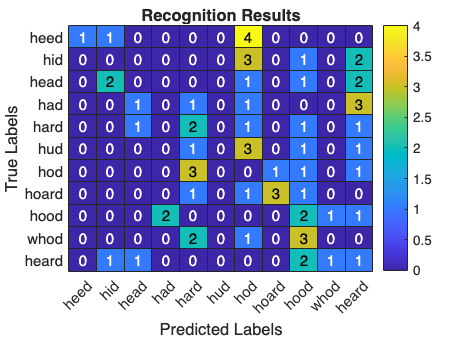

Confusion Matrix:
             heard    hood    heed    had    hid    hoard    head    hod    hard    hud    whod
             _____    ____    ____    ___    ___    _____    ____    ___    ____    ___    ____

    heard      1       2       0       0      1       0       1       0      0       0      1  
    hood       1       2       0       2      0       0       0       0      0       0      1  
    heed       0       0       1       0      1       0       0       4      0       0      0  
    had        3       0       0       0      0       0    

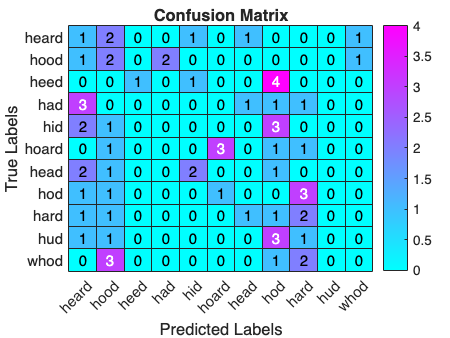

Calculating Metrics...
Class-wise Precision:
     heard       hood      heed    had    hid    hoard    head    hod    hard    hud    whod
    ________    _______    ____    ___    ___    _____    ____    ___    ____    ___    ____

    0.083333    0.15385     1       0      0     0.75      0       0     0.2      0      0  

Class-wise Recall:
     heard      hood       heed      had    hid    hoard    head    hod     hard      hud    whod

Test_hmm_recognizer('features/Test_MFCC', words, trained_hmm_folder);


% Custom Features
disp('Testing on Custom Data...');

Testing on Custom Data...


Processing file: sp01a_w05_hard for true label: hard
Processing file: sp01a_w10_whod for true label: whod
Processing file: sp03a_w02_hid for true label: hid
Processing file: sp03a_w03_head for true label: head
Processing file: sp03a_w08_hoard for true label: hoard
Processing file: sp06a_w04_had for true label: had
Processing file: sp07a_w03_head for true label: head
Processing file: sp08a_w04_had for true label: had
Processing file: sp09a_w11_heard for true label: heard
Processing file: sp10a_w01_heed for true label: heed
Processing file: sp13a_w07_hod for true label: hod
Processing file: sp13a_w09_hood for true label: hood
Processing file: sp14a_w02_hid for true label: hid
Processing file: sp14a_w06_hud for true label: hud
Processing file: sp14a_w08_hoard for true label: hoard
Processing file: sp15a_w06_hud for true label: hud
Processing file: sp16a_w01_heed for true label: heed
Processing file: sp16a_w10_whod for true label: whod
Processing file: sp18a_w04_had for true label: had
Pro

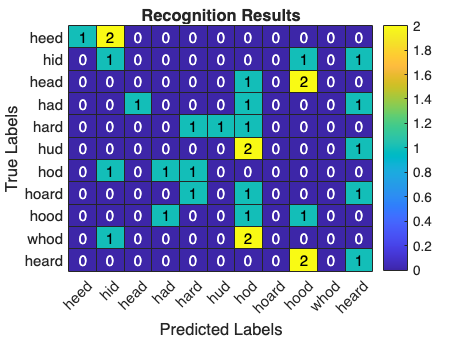

Confusion Matrix:
             hard    whod    hid    head    hoard    had    heard    heed    hod    hood    hud
             ____    ____    ___    ____    _____    ___    _____    ____    ___    ____    ___

    hard      1       0       0      0        0       0       0       0       1      0       1 
    whod      0       0       1      0        0       0       0       0       2      0       0 
    hid       0       0       1      0        0       0       1       0       0      1       0 
    head      0       0       0      0        0       0    

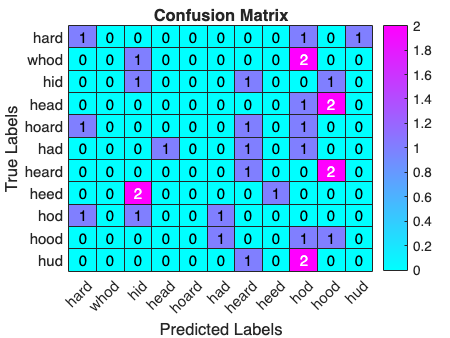

Calculating Metrics...
Class-wise Precision:
     hard      whod    hid    head    hoard    had    heard    heed    hod     hood      hud
    _______    ____    ___    ____    _____    ___    _____    ____    ___    _______    ___

    0.33333     0      0.2     0        0       0      0.2      1       0     0.16667     0 

Class-wise Recall:
     hard      whod      hid      head    hoard    had     heard      heed      hod     hood      hud</

Test_hmm_recognizer('features/Custom_MFCC', words, trained_hmm_folder);